height = [0.69,9.05,10.95,11.83,12.4,12.84,13.2,13.5,13.8,14.1,14.3,14.53,14.75,14.95,14.9,15.15,15.3,15.46,15.69,15.83,15.93,16.09,16.2,16.32,16.47,16.57,16.72,16.83,16.93,17.06,17.189,17.3,17.4,17.5,17.6,17.78,18];
water_vol1 = linspace(0,1700,35);
water_vol2 = [1800,1900];
water_vol1(end+1:end+2) = water_vol2;
figure(1)
plot(height,water_vol1,"ro")
yline(1550) % top of triangular area
hold on
yline(50) % top of square area

% p is the coefficient for 3 degree polynomial formula calculating volume in the triangular
% area based on hieght

P = polyfit(height(3:end-6),water_vol1(3:end-6),3)

P = 	1.0e+03 *

    0.0007    0.0068   -0.3859    2.6059


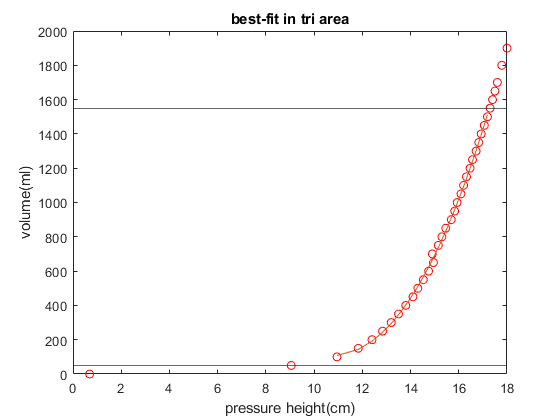

y = polyval(P,height(3:end-6));
plot(height(3:end-6),y)
xlabel("pressure height(cm)")
ylabel("volume(ml)")
title("best-fit in tri area")


figure(2)
Q = polyfit(height(end-6:end),water_vol1(end-6:end),1)

Q = 	1.0e+03 *

    0.5010   -7.1160


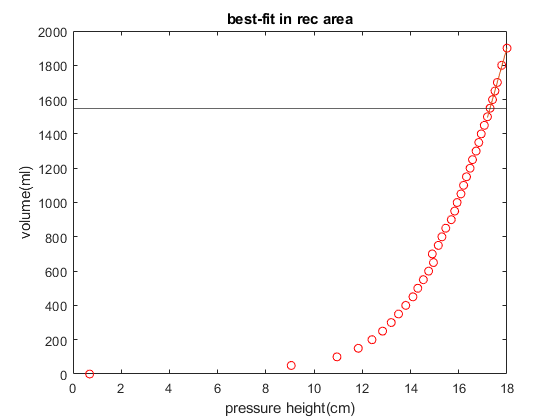

y2 = polyval(Q,height(end-6:end));
plot(height,water_vol1,"ro")
hold on
plot(height(end-6:end),y2)
yline(1550) % top of triangular area
xlabel("pressure height(cm)")
ylabel("volume(ml)")
title("best-fit in rec area")